# Cooperative Transportation

Starting from Angelo Cenedese paper and Matteo Civiero thesis.

clear all;
close all;
warning('off');

## ROBOT DYNAMICS

The robots used in this project are based on the unicycle model.

State: $q(t) = [ x(t)\ y(t)\ \theta(t)] $

Input: $u(t) = [v(t)\ \omega(t)]
$

% System parameters
sys.n = 3;
sys.m = 2;
sys.Ts = 0.1; % sample time

% Initial state/position
x0 = [10; 14; 0];

## ALGORITHM PARAMETERS

% proximity parameter to the goal position (tolleranza per il goal)
delta = 0.1;

### COMMON PARAMETERS

% weight for intermediate states
W_weight = 10;
% weight for inputs
R_weight = 1;
% weight for last state only
Z_weight = 1;

% predictive horizon
N = 20;
Px = [1 0 0; 0 1 0];

policy_halt = false;
k_loose_grip = 3;
eps_loose_grip = 0.01;

## LEADER PARAMETERS

leaderParams.W = W_weight*eye(sys.n);       
leaderParams.R = R_weight*eye(sys.m);
leaderParams.Z = Z_weight*eye(sys.n);

leaderParams.Px = Px; % Px in the paper

#### Linear and angular velocities limits

leaderParams.v_max = 1; %0.25
leaderParams.w_max = pi/2; %2.8

#### Plotting parameters

leaderParams.pos_color = "red";
leaderParams.pred_color = "magenta";
leaderParams.constraint_color = "yellow";
leaderParams.show_predictions = true;
leaderParams.show_constraints = true;
leaderParams.keep_predictions = false;

% initial shape of leader
th = 0:0.3:2*pi;
leaderParams.initRobotShape = 0.32*[cos(th); sin(th)];
leaderParams.robotShape = leaderParams.initRobotShape;

## FOLLOWER PARAMETERS

% relative distance from leader to follower to have
followerParams.d_FL = 1;
followerParams.d_FL_sq = repmat(followerParams.d_FL^2, [1,N]);
% relative cost for distance errors
followerParams.C = 5000;
% limit on follower linear velocity, to be higher than leader
followerParams.v_max = 1.5;
% limit on follower angular velocity, to be higher than leader
followerParams.w_max = pi; 
% exponential decay of tracking quality over the prediction
followerParams.beta = 0.95;
followerParams.beta_N = followerParams.beta.^(1:N);

followerParams.Px = Px; % Px in the paper

#### Plotting parameters

followerParams.pos_color = "blue";
followerParams.pred_color = "cyan";
followerParams.constraint_color = "green";
followerParams.show_predictions = true;
followerParams.show_constraints = false;
followerParams.keep_predictions = false;
followerParams.initRobotShape = (0.2*[-1, 1, 1, -1; -1, -1, 1, 1]...
                            +followerParams.d_FL*[-1,0, 0, -1; 0,0,0,0]);
followerParams.robotShape =followerParams.initRobotShape;

## OBSTACLE PARAMETERS

    %---------------------%
    %       no_obs        %
    %       one_obs       %
    %       two_obs       %
    %       three_obs     %
    %       pathological  %
    %       six_obs       %
    %       valzer        %
    %---------------------%


[x0, obstacles] = setupEnvironment("valzer");

## MPC IMPLEMENTATION

Variable meaning:

- $x_l$, $x_f$ = actual states of leader and 

- X_L, X_L_stacked = preferred path by leader, n x N and nN x 1 the stacked

- real_d = actual distance between robots

#### Loop variables

goal_reached = false;
max_iter = 500;
i = 1;

Initialization of the leader and follower STATES and INPUTS

x_l(:,i) = x0;
x_f(:,i) = x0 + [followerParams.d_FL; 0; 0];

    % initial guesses for optimal inputs
U_l_old = zeros([sys.m*N,1]);
U_f_old = zeros([sys.m*N,1]);

#### Start the plot

figure; 
set(gcf,'Visible','on'); hold on; grid on;
    % Plotting both robots and load
sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), x_f(:, 1), N, obstacles);
    % Just plotting the leader
% sp = SystemPlotter(leaderParams, followerParams, x_l(:,1), [], N, obstacles);
tit = title("Iteration 1, time: 0s");

tic

#### MPC algorithm

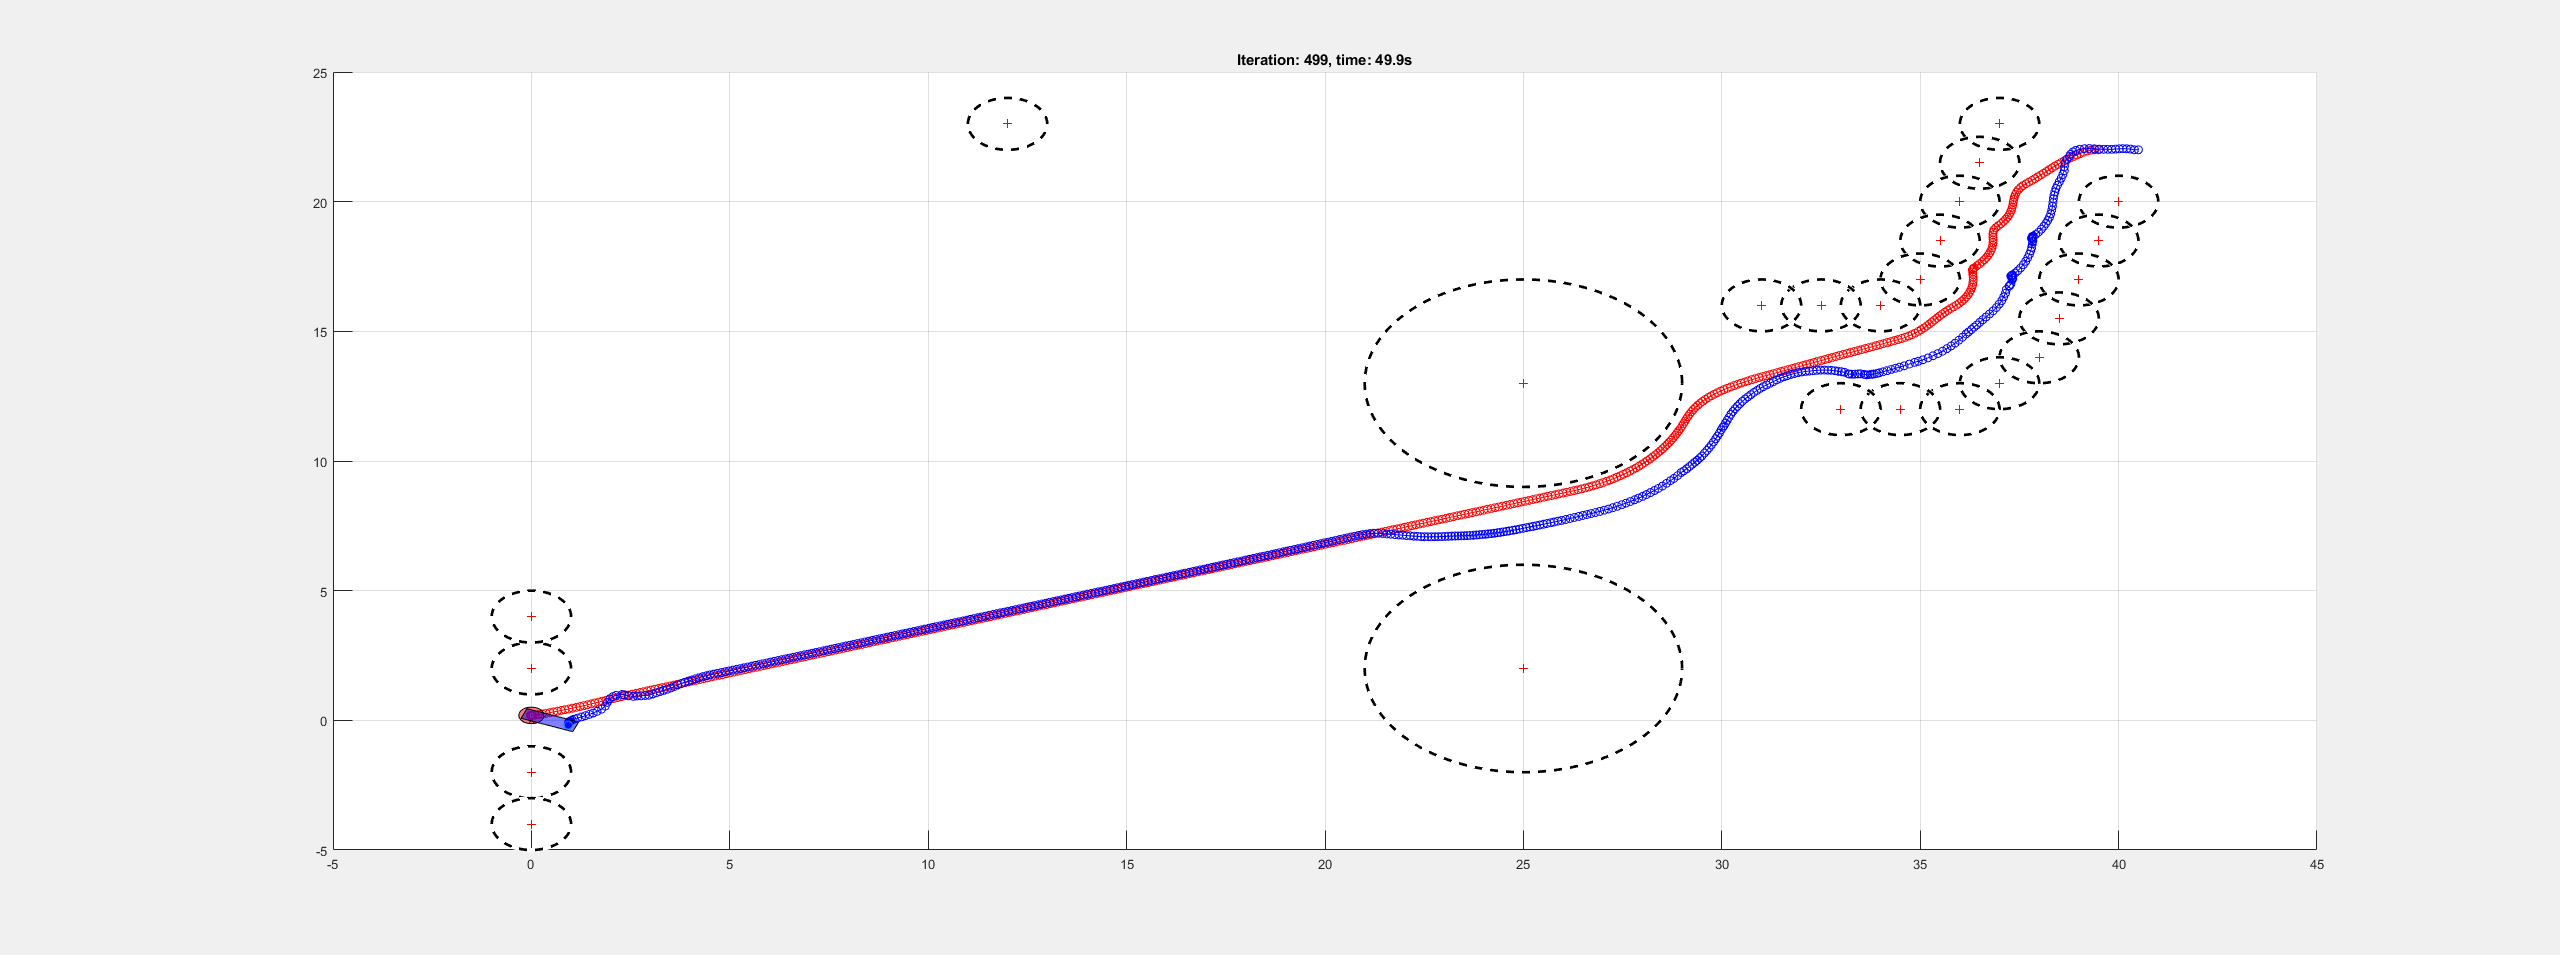

while (~goal_reached) && (i < max_iter) % terminal condition: goal reach or maximum iteration

        % Evaluate the MPC only on the nearest obstacles
    obstaclesInRange = checkObstacles(obstacles, x_l(1:2,i), N, leaderParams.v_max);

        % MPC for the leader
    [x_l(:,i+1), X_L, X_L_stacked, qi_leader, ~, U_l_old] = leaderMPCandUpdate( ...
                        sys, x_l(:,i), N, leaderParams, obstaclesInRange, U_l_old);

        % MPC for the follower
    [x_f(:,i+1), X_F, qi_follower, ~, U_f_old] = followerMPCandUpdate(...
                        sys, x_f(:,i), X_L_stacked, N, followerParams, obstaclesInRange, U_f_old);

%--------------------------- Feasibility-Aware Recovery Policy -------------

    if policy_halt 
            % Check if trajectory does not loose the load
        formation_error = abs(vecnorm(Px*(X_L-X_F))-followerParams.d_FL);
        if any(formation_error(1:k_loose_grip) > eps_loose_grip)

                % MPC for the leader using the new cost function
            [x_l(:,i+1), X_L, X_L_stacked, qi_leader, ~, U_l_old] = leaderMPCandUpdateHalt( ...
                        sys, x_l(:,i), N, leaderParams, obstaclesInRange, zeros([sys.m*N,1]));

                % MPC for the follower using the new leader states
            [x_f(:,i+1), X_F, qi_follower, ~, U_f_old] = followerMPCandUpdate(...
                        sys, x_f(:,i), X_L_stacked, N, followerParams, obstaclesInRange, zeros([sys.m*N,1]));
        end
    end

%--------------------------- Other evaluations and plot update ---------------

        % Get the instantaneous rotation of load and apply to load
    fl_diff = x_f(:,i+1) - x_l(:,i+1);
    loadTheta = atan2(fl_diff(2), fl_diff(1));

    leaderParams.robotShape = Rmat(loadTheta)*leaderParams.initRobotShape;
    followerParams.robotShape = Rmat(loadTheta)*followerParams.initRobotShape;

        % Check if goal was reached up to desired precision
    if norm(x_l(1:2,i+1)) < delta
        goal_reached = true;
    end

        % Distance between the 2 robots
    real_d(i) = norm(x_l(1:2,i) - x_f(1:2,i));

        % Do the plotting
    sp.updateLeaderPath(x_l(:,i), X_L);
    sp.updateLoadPos(x_l(:,i), x_f(:,i), loadTheta);
    sp.updateFollowerPath(x_f(:,i), X_F);

    if size(obstacles, 1) ~= 0
        sp.updateObstacles(obstacles, size(obstacles, 1))
    end
    
    tit.String = "Iteration: " + num2str(i) + ", time: " + num2str(i*sys.Ts) + "s";
    sp.redraw();

        % Obstacle dynamics 
    if size(obstacles, 2) >= 20
        obstacles{20}.center = obstacles{20}.center - [0, 0.1]'; 
    end

    step_time(i) = toc;

        % Update iteration
    i = i+1;

end

## Results plot

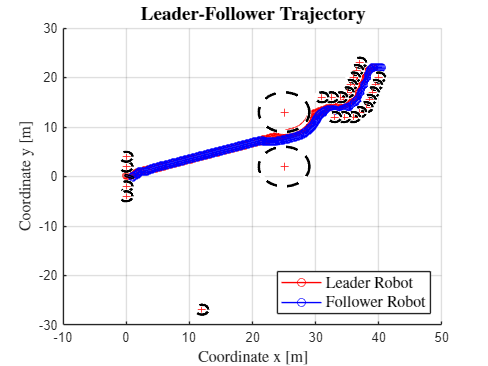

time = 0:sys.Ts:sys.Ts*(i-1);
%Trajectory plot
figure;  hold on; grid on;
plot( x_l(1,:), x_l(2,:), "-o","Color", "red");
plot( x_f(1,:), x_f(2,:), "-o","Color", "blue")
plotObstacles(obstacles);
plot(...
    polyshape(x_f(1,end)+followerParams.robotShape(1,:),...
              x_f(2,end)+followerParams.robotShape(2,:)),...
    'FaceColor',followerParams.pos_color,'FaceAlpha',0.5);
title("\textbf{Leader-Follower Trajectory}","Interpreter","latex", "FontSize", 14)
xlabel("Coordinate x [m]","Interpreter","latex", "FontSize", 12)
ylabel("Coordinate y [m]","Interpreter","latex", "FontSize", 12)
legend("Leader Robot","Follower Robot","Location","southeast","Interpreter","latex", "FontSize", 12)

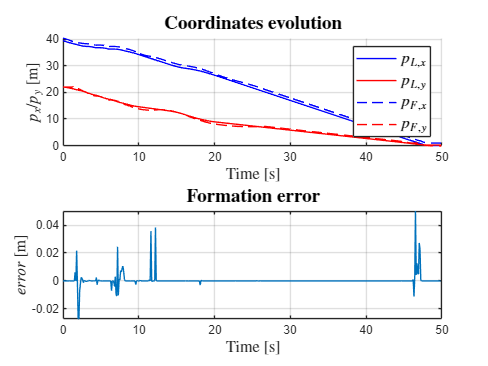


%Coordinates evolution and formation error plot
figure; 
subplot(2,1,1)
hold on; grid on;
plot(time, x_l(1,:), "-b", time, x_l(2,:), "-r");
plot(time, x_f(1,:), "--b", time, x_f(2,:), "--r");
xlabel("Time [s]", "Interpreter","latex","FontSize", 12)
ylabel("$p_x$/$p_y$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Coordinates evolution}", "Interpreter","latex", "FontSize", 14)
legend("$p_{L,x}$","$p_{L,y}$","$p_{F,x}$","$p_{F,y}$","Interpreter","latex", "FontSize", 12)

subplot(2,1,2)
plot(time(1:end-1),real_d - followerParams.d_FL);
grid on;
xlabel("Time [s]", "Interpreter","latex", "FontSize", 12)
ylabel("$error$ [m]", "Interpreter","latex", "FontSize", 12)
title("\textbf{Formation error}", "Interpreter","latex", "FontSize", 14)